close all;
clear all;

A=xlsread('sample_2_068_tension_1.csv');
[yave1,dave1,Y1,pos]=data_ave_and_bocplot(A);
figure('DefaultAxesFontSize',17,'position', [50 50 600 480])
color.code=colormap(slanCM(160));

@author : slandarer


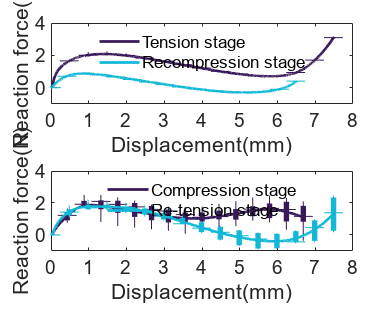

color.l=length(color.code);
color.index1=round(color.l*2/9);
color.index2=round(color.l*5/9);
color.index3=round(color.l*7/9);
subplot(2,1,1)
boxplot(Y1,'positions',pos,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave1,yave1,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
B=xlsread('sample_2_068_compression_1.csv');
[yave2,dave2,Y2,pos2]=data_ave_and_bocplot(B);
boxplot(Y2,'positions',pos2,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave2,yave2,'Color',color.code(color.index3,:),'LineWidth',2);
axis([0 8 -1 4]);
xticks(0:1:8);
xticklabels({'0','1','2','3','4','5','6','7','8'});
lgd1=legend('Tension stage','Recompression stage');
ylabel('Reaction force(N)');
xlabel('Displacement(mm)');
legend('Location','north','FontName','Arial');
legend('boxoff');
ax=gca;
ax.FontName='Arial';


C=xlsread('compression_module_1.csv');
%C=C(1:3204,:);
[yave3,dave3,Y3,pos3]=data_ave_and_bocplot(C);
subplot(2,1,2)
boxplot(Y3,'positions',pos3,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave3,yave3,'Color',color.code(color.index1,:),'LineWidth',2);
D=xlsread('compression_module_tension_test_1.csv');
%D=D(10164:end,:);
[yave4,dave4,Y4,pos4]=data_ave_and_bocplot(D);
boxplot(Y4,'positions',pos4,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave4,yave4,'Color',color.code(color.index3,:),'LineWidth',2);
axis([0 8 -1 4]);
lgd2=legend('Compression stage','Re-tension stage');
xticks(0:1:8);
xticklabels({'0','1','2','3','4','5','6','7','8'});
ylabel('Reaction force(N)','FontName','Arial');
xlabel('Displacement(mm)','FontName','Arial');
legend('Location','north','FontName','Arial');
legend('boxoff');
ax=gca;
ax.FontName='Arial';